# Types of Wavelet Transform

In this notebook, we will look at a couple of activities to deepen our undertansding of wavelet transfor and learn about the two types of Wavelet transform.

### Continuous Wavelet Transform

**Below is the equation of Continuous Wavelet transform:**


$$W\left(a,b\right)=\frac{1}{\sqrt{a}}\int_{-\infty }^{\infty } x\left(t\right)\;\psi^{\ast } \frac{\left(t-b\right)}{a}\textrm{dt}$$
 

Where $\psi \;\textrm{is}\;\textrm{the}\;\textrm{wavelet}\;\textrm{function}\;,b\;\textrm{is}\;\textrm{the}\;\textrm{translation}\;\textrm{parameter}\;\textrm{and}\;a\;\textrm{is}\;\textrm{scale}\;\textrm{parameter}$

***But this is a 2D function, something like an image!!!! and *****where is frequency in this equatio!!!**. 

- Wavelet transform is a 2D function, that allows time-frequency analysis.

- Scales can be converted to  pseudo-frequencies using this equation $f_a =\frac{f_c }{a}$, where fc is the central frequency and fa is the scale corresponding frequency.

- In MATLAB, you can use [`scal2frq`](https://www.mathworks.com/help/wavelet/ref/scal2frq.html#responsive_offcanvas) command to convert Scale to Frequency.

### CWT MATLAB Command

Use `cwt` to compute and visualize Continuous 1-D wavelet transform.

load mtlb % speech signal
cwt(mtlb,"bump",Fs)
[wtMTRX, wtFreq] = cwt(mtlb,"bump",Fs)
abs(wtMTRX)
imagesc(abs(wtMTRX))

## **Discrete Wavelet Transform**

There are two families of wavelet transforms: Continuous Wavelet Transform, the one we dicussed above adn Discrete Wavelet Transform. The key idfferent between these two types is that the CWT uses every possible wavelet over a range of scales and time locations, means an infnite number of scales and locations. On the other hand, DWT uses a finite set of waveletsdefined at a particular set scales and discrete time(discrete locations). the equation of DWT can be written as below:


$$W_{m,n} =\int_{-\infty }^{\infty } x\left(t\right)\;\psi_{m,n} \left(t\right)\textrm{dt}$$
 


$$m\;\textrm{is}\;\textrm{the}\;\textrm{scale}\;\textrm{and}\;n\;\textrm{is}\;\textrm{the}\;\textrm{translation}\;\ldotp \textrm{Both}\;\textrm{are}\;\textrm{discrete}\;$$


### DWT Implementation Algorithm

Starting from a signal s of length N, two sets of coefficients are computed: approximation coefficients cA1, and detail coefficients cD1. Convolving s with the scaling filter LoD, followed by dyadic decimation, yields the approximation coefficients. Similarly, convolving s with the wavelet filter HiD, followed by dyadic decimation, yields the detail coefficients.

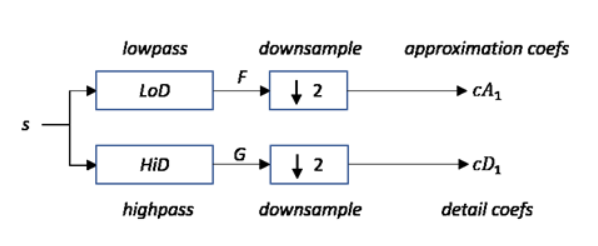

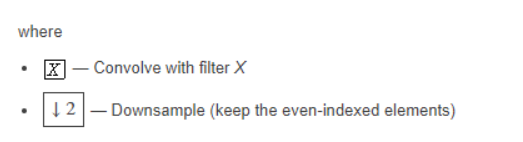

### DWT MATLAB Command

Use `dwt` to perform Single-level 1-D discrete wavelet transform

[cApprox,cDetail] = dwt(mtlb,'sym4');
xrec = idwt(cApprox,zeros(size(cApprox)),'sym4');
plot(mtlb)
hold on
grid on
plot(xrec)
legend('Original','Reconstruction')

## **Wavelet Families**

Print wavelet families and family members

waveletfamilies